## **Author: MatNoble_HUST **

## **Date: 2019_6_2**

**Poisson Equation**


$$-\frac{d}{d x}\left(c(x) \frac{d u(x)}{d x}\right)=f(x), a<x<b$$


multiply v(x) and integral


$$-\int_{a}^{b} \frac{d}{d x}\left(c(x) \frac{d u(x)}{d x}\right) v(x) d x=\int_{a}^{b} f(x) v(x) d x$$


integration by parts 


$$-c(b) u^{\prime}(b) v(b)+c(a) u^{\prime}(a) v(a)+\int_{a}^{b} c u^{\prime} v^{\prime} d x=\int_{a}^{b} f v d x$$


and $v(a)=v(b)=0$. then


$$\int_{a}^{b} c u^{\prime} v^{\prime} d x=\int_{a}^{b} f v d x$$


i. e. **weak formulation**

find $u \in H^{1}(1)$ such that


$$a(u, v)=(f, v)$$
 

for any $v \in H_{0}^{1}(I)
$ where $I=(a, b)$.

further, **Galerkin formulation**

find $u_{h} \in U_{h}$ such that


$$a\left(u_{h}, v_{h}\right)=\left(f, v_{h}\right)$$



$$\Leftrightarrow \int_{a}^{b} c u_{h}^{\prime} v_{h}^{\prime} d x=\int_{a}^{b} f v_{h} d x$$


for any $v_{h} \in U_{h}^{0}$ where $I=(a, b)$.

% [N_s, error_max] = Poisson_1D(x1, xn, number_of_elements, p, basis_type, Gauss_type, Boundary_type)
% x1, x2 ： left and right endpoints
% number of mesh elements
% p : Degree of distortion
% basis_type : 
              % 101 : 1D linear
              % 102 : 1D quadratic
% Gauss_type : 2, 4, 8

%%%%%% 
u = @(x)(x .* cos(x));

u_x = @(x)(cos(x)-x*sin(x));

c = @(x)(exp(x));

f = @(x)(-exp(x) * (cos(x) - 2*sin(x) - x*cos(x) - x*sin(x)));
%%%%%% 

%%%%%% Example 1
x1 = 0;    xn = 1;
number_of_elements = 8;
p = 0.4; 
basis_type = 101; % 1D linear
Gauss_type = 8;
Boundary_type = [2, 1]; % Neumann
[solution1, error_max1] = Poisson_1D(u, u_x, c, f, x1, xn, number_of_elements,...
                                     p, basis_type, Gauss_type, Boundary_type)

solution1 =     0.0018
    0.2115
    0.3053
    0.3855
    0.4727
    0.5167
    0.5569
    0.5572
    0.5403


error_max1 = 0.0018

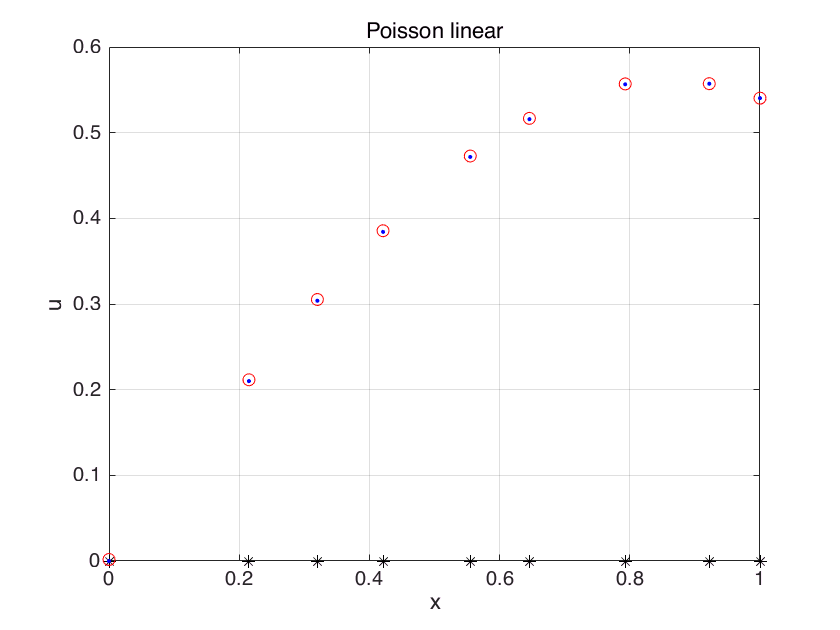

grid on
title('Poisson linear')
xlabel('x')
ylabel('u')


%%%%%% Example 2
x1 = 0;    xn = 1;
number_of_elements = 4;
p = 0.4; 
basis_type = 102; % 1D quadratic
Gauss_type = 8;
Boundary_type = [2, 1]; % Neumann
[solution2, error_max2] = Poisson_1D(u, u_x, c, f, x1, xn, number_of_elements,...
                                     p, basis_type, Gauss_type, Boundary_type)

solution2 =    -0.0000
    0.0831
    0.1644
    0.2772
    0.3772
    0.4600
    0.5204
    0.5601
    0.5403


error_max2 = 5.1047e-05

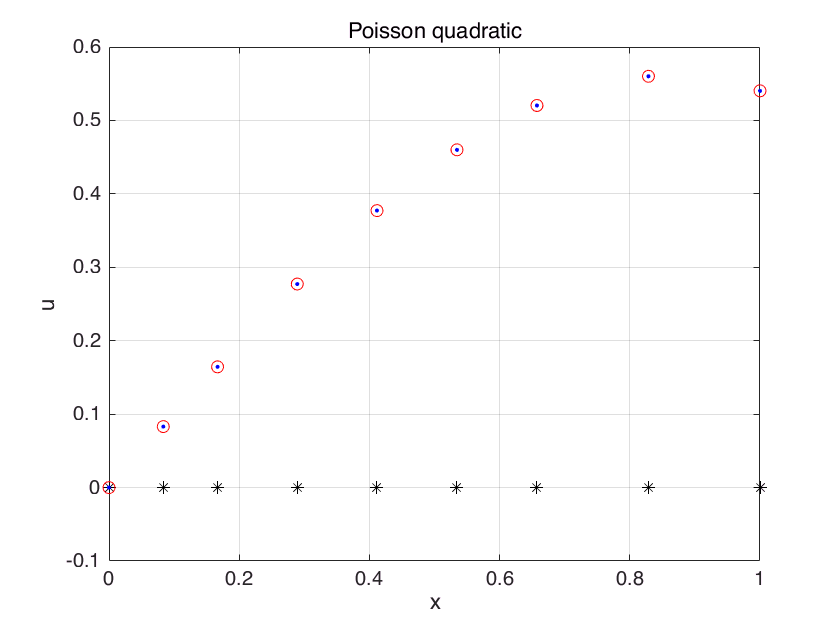

grid on
title('Poisson quadratic')
xlabel('x')
ylabel('u')